clc; clear; close all

# Load 1D-FC Data

f = @(x, y) cos(5*x.^2+y.^2)

f = function_handle with value:
    @(x,y)cos(5*x.^2+y.^2)



C = 27;
d = 5;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

# Constructing Boundary Patch

## C2 Patch

Needs l(theta) data, the corners on the boundary in terms of theta, and function values on mesh

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

theta_C = 0;
theta_A = 0.4;
theta_B = 2*pi-0.4;

l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around

M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];

n_xi = 20;
n_eta = 20;

xi_mesh = linspace(0, 1, n_xi+1);
eta_mesh = linspace(0, 1, n_eta+1);

[XI, ETA] = meshgrid(xi_mesh, eta_mesh);
XY = M_p(XI(:), ETA(:));

f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);

C2_patch = Q_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY) % data associated with patch

C2_patch =   Q_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+l_theta(l_B(eta))-l_theta(theta_C)
            J: @(v)[theta_A*cos(v(1)*theta_A/2),(theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2);-theta_A*cos(v(1)*theta_A),-(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)]
         n_xi: 20
        n_eta: 20
     xi_start: 0
       xi_end: 1
    eta_start: 0
      eta_end: 1
         f_XY: [21×21 double]
        x_min: 2.449293598294706e-16
        x_max: 7.946773231802455e-01
        y_min: -3.894183423086503e-01
        y_max: 3.894183423086510e-01



[X, Y] = C2_patch.xy_mesh();
figure;
scatter(X(:), Y(:));
hold on;

## S Patch

theta_A = 0.2;
theta_B = pi+0.2;

l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)];
H = 0.17;

M_p = @(xi, eta) l_theta(l_A(xi)) + eta.*H.*nu(xi);
theta_diff = theta_B - theta_A;
J = @(v) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];

n_xi = 150;
n_eta = 10;

xi_mesh = linspace(0, 1, n_xi+1);
eta_mesh = linspace(0, 1, n_eta+1);

[XI, ETA] = meshgrid(xi_mesh, eta_mesh);
XY = M_p(XI(:), ETA(:));

f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);

S_patch = Q_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY)

S_patch =   Q_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+eta.*H.*nu(xi)
            J: @(v)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
         n_xi: 150
        n_eta: 10
     xi_start: 0
       xi_end: 1
    eta_start: 0
      eta_end: 1
         f_XY: [11×151 double]
        x_min: 1.996668332936563e-01
        x_max: 1.999977723952962e+00
        y_min: -9.999554481540360e-01
        y_max: 1.986693307950613e-01


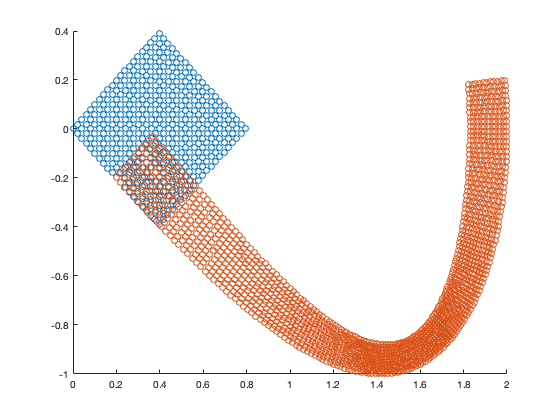


[X, Y] = S_patch.xy_mesh();
scatter(X(:), Y(:))

# FC on C2 Patch and S Patch

Assumes we know what type the patches are, if not, we can simply add another entry that is enumeration of the patch types

% creates patch with data, including partition of unity
C2_fcont_patch = C2_patch.C2_FC(C, d, A, Q)

C2_fcont_patch =   Q_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+l_theta(l_B(eta))-l_theta(theta_C)
            J: @(v)[theta_A*cos(v(1)*theta_A/2),(theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2);-theta_A*cos(v(1)*theta_A),-(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)]
         n_xi: 47
        n_eta: 47
     xi_start: -1.350000000000000e+00
       xi_end: 1
    eta_start: -1.350000000000000e+00
      eta_end: 1
         f_XY: [48×48 double]
        x_min: -1.066925746755325e+00
        x_max: 7.946773231802455e-01
        y_min: -9.035543339617642e-01
        y_max: 9.035543339617642e-01


S_fcont_patch = S_patch.S_FC(C, d, A, Q)

S_fcont_patch =   Q_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+eta.*H.*nu(xi)
            J: @(v)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
         n_xi: 150
        n_eta: 37
     xi_start: 0
       xi_end: 1
    eta_start: -2.700000000000000e+00
      eta_end: 1
         f_XY: [38×151 double]
        x_min: -2.501837259354737e-01
        x_max: 2.458957274655665e+00
        y_min: -1.336721731777335e+00
        y_max: 2.444928690359554e-01


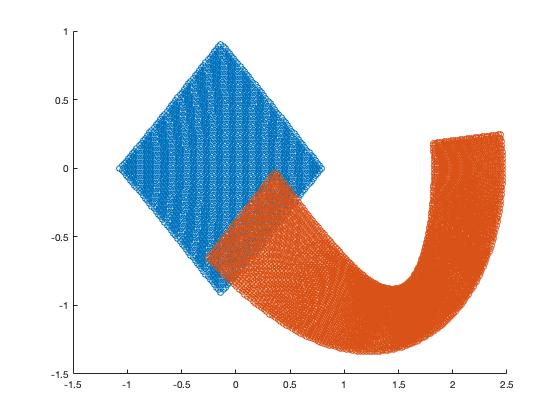


% domain of continued patches
[X_C2, Y_C2] = C2_fcont_patch.xy_mesh();
[X_S, Y_S] = S_fcont_patch.xy_mesh();

figure;
scatter(X_C2(:), Y_C2(:))
hold on;
scatter(X_S(:), Y_S(:))

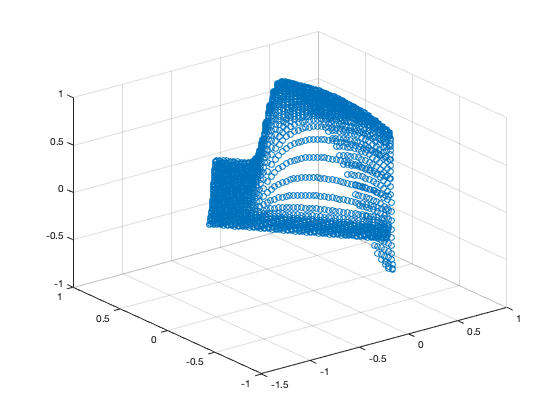


figure;
scatter3(X_C2(:), Y_C2(:), C2_fcont_patch.f_XY(:))

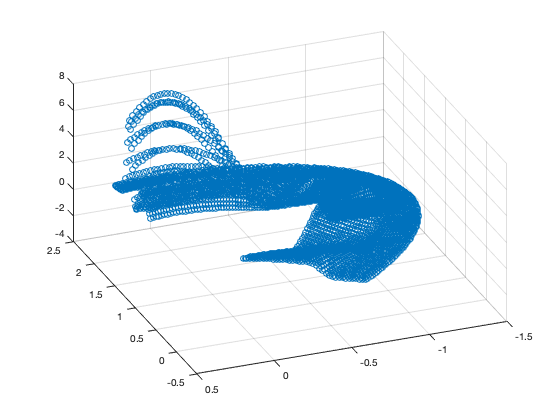


figure;
scatter3(X_S(:), Y_S(:), S_fcont_patch.f_XY(:))

# Interpolation onto R

Note that we don't have any interior patches, so if any points aren't in the C2 or S patch, we just assume we know the value.

R_x_bounds = [C2_fcont_patch.x_min, S_fcont_patch.x_max];
R_y_bounds = [S_fcont_patch.y_min, S_fcont_patch.y_max];

h_R = 0.02;

[R_X, R_Y] = meshgrid(R_x_bounds(1):h_R:R_x_bounds(2), R_y_bounds(1):h_R:R_y_bounds(2));
f_R = NaN(size(R_X))

f_R =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

for i = 1:size(R_X, 1)
    for j = 1:size(R_X, 2)
        x = R_X(i, j);
        y = R_Y(i, j);
        
        [f_C2, phi_C2, in_range_C2] = C2_fcont_patch.locally_compute(x, y, d);
        [f_S, phi_S, in_range_S] = S_fcont_patch.locally_compute(x, y, d);
        
        if in_range_C2 && in_range_S
            f_R(i, j) = (f_C2*phi_C2 + f_S*phi_S)/(phi_C2+phi_S);
        elseif in_range_C2
            f_R(i, j) = f_C2;
        elseif in_range_S
            f_R(i, j) = f_S;
        end
    end
end

[XI, ETA] = S_patch.xi_eta_mesh();
phi_S = S_patch.phi(XI, ETA)

phi_S =                          0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0                         0    

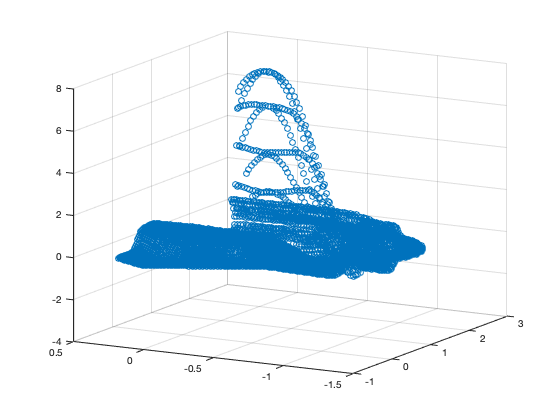

figure;
scatter3(R_X(~isnan(f_R)), R_Y(~isnan(f_R)), f_R(~isnan(f_R)))

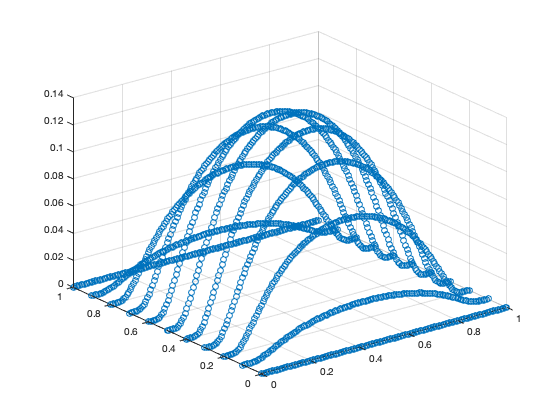


figure;
scatter3(XI(:), ETA(:), phi_S(:))

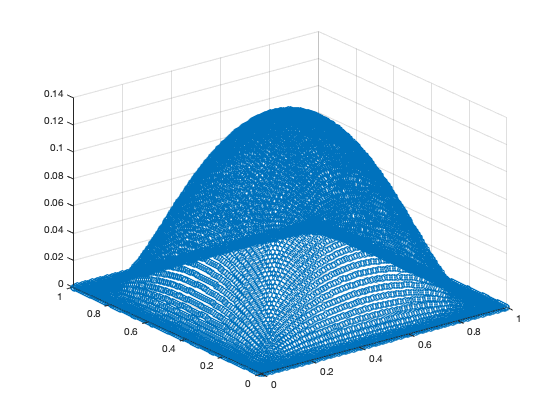

phi_xy = @(x, y) exp(-1./(1-(2*x-1).^2)).*exp(-1./(1-(2*y-1).^2));
[X, Y] = meshgrid(linspace(0, 1, 100));
figure;
scatter3(X(:), Y(:), phi_xy(X(:), Y(:)))

% function f_y = f(x, y)
%     r = sqrt(x.^2 + y.^2);
%     f_y = zeros(size(x));
%     f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
%     f_y(r >= 0.56) = 0;
% end